## **Péndulo de Pohl**

El péndulo de Pohl es un péndulo de torsión constituido por un volante o disco metálico que puede rotar alrededor de un eje y que, mediante un resorte espiral, recupera su posición de equilibrio, oscilando alrededor de ésta. 

El estudio de este tipo de péndulos accionados por resorte en espiral tiene numerosas aplicaciones en la ingeniería y incluso en el día a día. Los relojes de pulsera mecánicos son un claro ejemplo, deben ajustarse muy bien las propiedades del resorte para que este tenga un movimiento periódico muy exacto. Uno de los mecanismos actuales más famoso y que usa este tipo de péndulos es el mecanismo *tourbillon* de algunos relojes y que ahora se muestra muchas veces en relojes de lujo como demostración de virtuosismo técnico.

Aquí, con datos reales de laboratorio, ajustaremos la curva de resonancia de un determinado péndulo de Pohl obteniendo parámetros caracterísicos del mismo ajustando la curva de resonancia


$$\[A=\frac{a}{\sqrt{(\omega ^2 - \omega_0 ^2)^2 +4\gamma^2 \omega ^2}}\]
$$


PARAMETER ESTIMATES
    p(1)		5.6184467379
    p(2)		10.3417950158
    p(3)		0.1893451352

GOODNESS OF FIT
    SSE:		0.0753505665
    R-square:		0.9946047138
    Adjusted R-square:	0.9922924482
    X2 percentile:	15.5073130559
    X2/dof:		1.9384141320
    dof:		8
    Confidence level:	0.9500000000


ans = 3×2 table
            Parameter_Minimum    Parameter_Maximun
            _________________    _________________

    p(1)      5.0566             6.1803           
    p(2)       8.481             11.376           
    p(3)    -0.21883             0.1728           


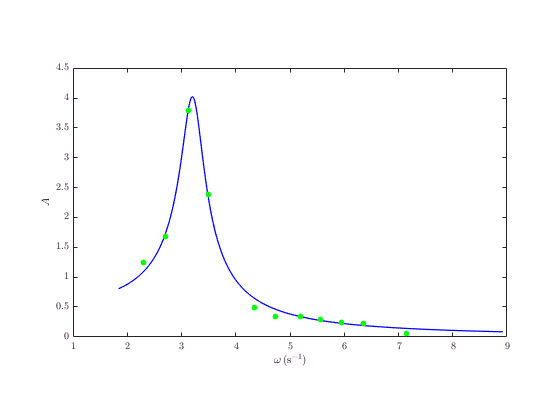

clear all; clc; close all

% Data
M = [3.12378700000000,3.79205259226382
       7.13957800000000,0.0484841915861459;
       2.69896300000000,1.67360632874642;
       2.29917500000000,1.25160426043701;
       3.49007700000000,2.38476476643719;
       4.34491800000000,0.491547867362077;
       4.73238300000000,0.340027913299259;
       5.19099900000000,0.333382751401243;
       5.56575900000000,0.291947770857485;
       5.94379500000000,0.241105406929550;
       6.34665200000000,0.215725081895537];
  x = M(:,1); y = M(:,2);
  
% Fitting model and p0 - initial seek
  model = @(x,p)  (p(1))./(sqrt((p(2) - x.^2).^2 + x.^2.*p(3) ));
  p0 = [5;11;0.2];

% Fit with NonLinearModelFit function
  labels.titlestr = '';                      
  labels.xlabelstr = '$\omega \, (\mathrm{s^{-1}})$'; 
  labels.ylabelstr = '$A$'; 
  [pf,P] = NonLinearModelFit(model,x,y,p0,0.95,labels);

## Determinación de la conductividad eléctrica de un material

Uno de los tests no desctructivos más importantes que se hace sobre conductores es sin duda el de la determinación de su conductividad, puesto que ha de cumplir unos ciertos requisitos dependiendo de a que deba aplicarse. En este caso vamos a emplear una idea bastante innovadora: hacer dicho test sobre un conductor cilíndrico sin la necesidad de tocar el material.

Aunque parezca una elucubración, sí puede conseguirse ésto haciendo uso de la teoría de propagación de ondas en conductores. Ésta nos dice que el campo eléctrico guarda una relación con la frecuencia


$$|\frac{E(\nu)}{E(0)}| = \frac{1}{\sqrt{\cosh^2 \beta  \sqrt{\nu} \, \cos^2 \beta \sqrt{\nu}  + \sinh^2 \beta  \sqrt{\nu} \, \sin^2 \beta  \sqrt{\nu} }}$$
 

siendo $\beta = \sqrt{\mu_0 \pi \sigma } d$.

PARAMETER ESTIMATES
    p(1)		0.0055679925

GOODNESS OF FIT
    SSE:		0.0206305604
    R-square:		0.9942563462
    Adjusted R-square:	0.9940266000
    X2 percentile:	38.8851386598
    X2/dof:		1.4955822561
    dof:		26
    Confidence level:	0.9500000000


ans = 1×2 table
            Parameter_Minimum    Parameter_Maximun
            _________________    _________________

    p(1)    0.0054195            0.0057219        


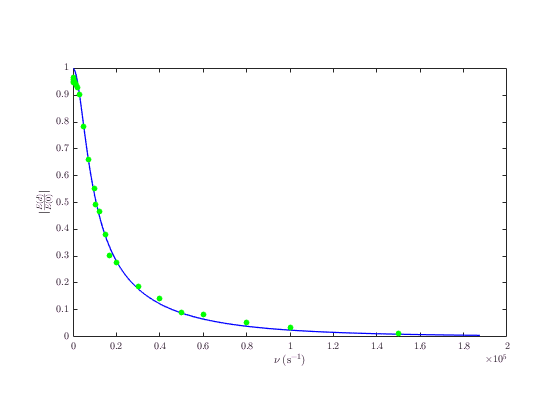

clear all; clc; close all

% Data
  M = [[100.000000, 0.958333];
       [200.000000, 0.964912]; 
       [300.000000, 0.952381]; 
       [400.000000, 0.948276]; 
       [500.000000, 0.952381]; 
       [700.000000, 0.947712]; 
       [1000.000000, 0.944444]; 
       [1250.000000, 0.944444]; 
       [1500.000000, 0.934343]; 
       [1750.000000, 0.934343]; 
       [2000.000000, 0.928571]; 
       [3000.000000, 0.900901]; 
       [5000.000000, 0.784314]; 
       [7000.000000, 0.659420]; 
       [10000.000000, 0.550725]; 
       [10500.000000, 0.493333]; 
       [12000.000000, 0.467949]; 
       [15000.000000, 0.381720]; 
       [17000.000000, 0.303030]; 
       [20000.000000, 0.277778]; 
       [30000.000000, 0.188596]; 
       [40000.000000, 0.141026]; 
       [50000.000000, 0.089744]; 
       [60000.000000, 0.081140]; 
       [80000.000000, 0.051802]; 
       [100000.000000, 0.032407]; 
       [150000.000000, 0.012626]];
  x = M(:,1); y = M(:,2);

% Fitting model and p0 - initial seek
  model = @(x,p) ((cosh(sqrt(2.*pi).*p(1).*sqrt(x)).*cos(sqrt(2.*pi).*p(1).*sqrt(x))).^2 + (sinh(sqrt(2.*pi).*p(1).*sqrt(x)).*sin(sqrt(2.*pi).*p(1).*sqrt(x))).^2).^(-1/2);
  p0 = [0.003]';

% Fit with NonLinearModelFit function
  labels.titlestr = '';                      
  labels.xlabelstr = '$\nu \, (\mathrm{s^{-1}})$'; 
  labels.ylabelstr = '$|\frac{E(d)}{E(0)}|$'; 
  [pf,P] = NonLinearModelFit(model,x,y,p0,0.95,labels);